ODE - Initial Value Problem - First Order

%doc ode45

r = 0.8;

dNdt = @(t, N) r*N

dNdt = function_handle with value:
    @(t,N)r*N


a = 0;
b = 10;

n0 = 1000;

[t, N] = ode45(dNdt, [a, b], n0)

t =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
    4.5000


N = 1.0e+06 *

    0.0010
    0.0015
    0.0022
    0.0033
    0.0050
    0.0074
    0.0110
    0.0164
    0.0245
    0.0366


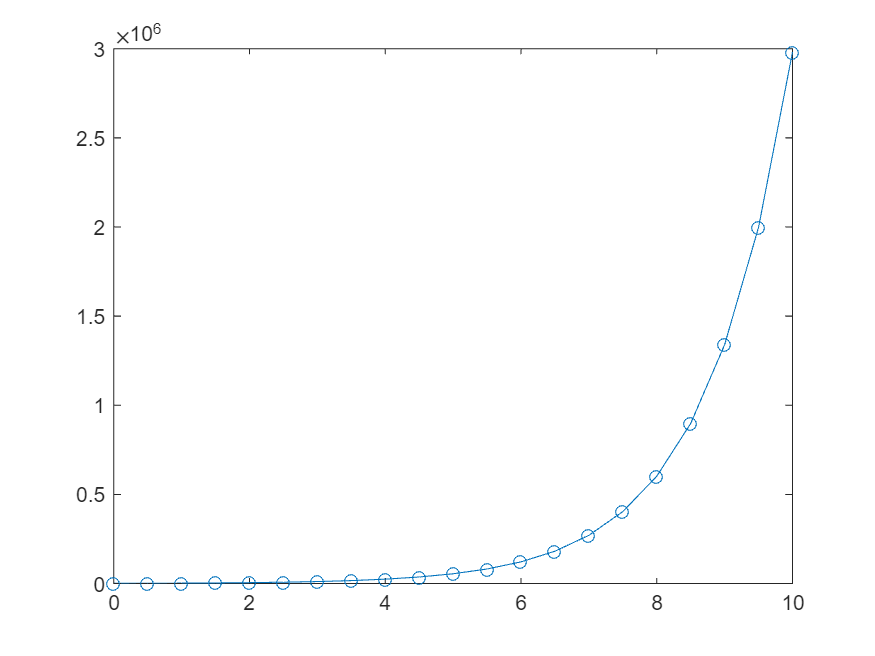


plot(t,N,'o-')


[t, N] = ode45(dNdt, [a:0.5:b], n0)

plot(t,N,'o-')

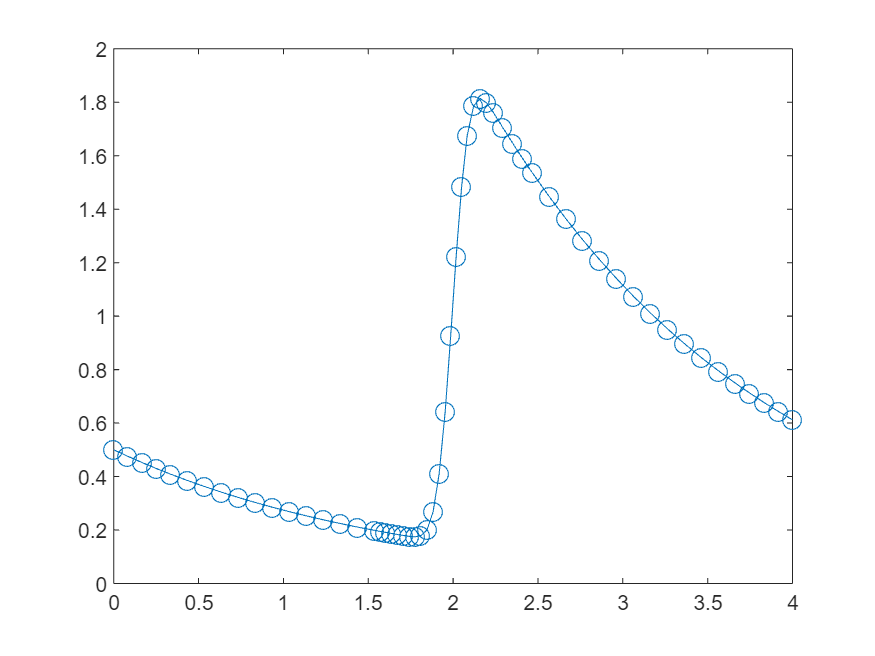

[t , y] = ode45(@dydt, [0, 4], 0.5);
plot(t,y,'-o','MarkerSize',9)

size(t)

ans =     57     1


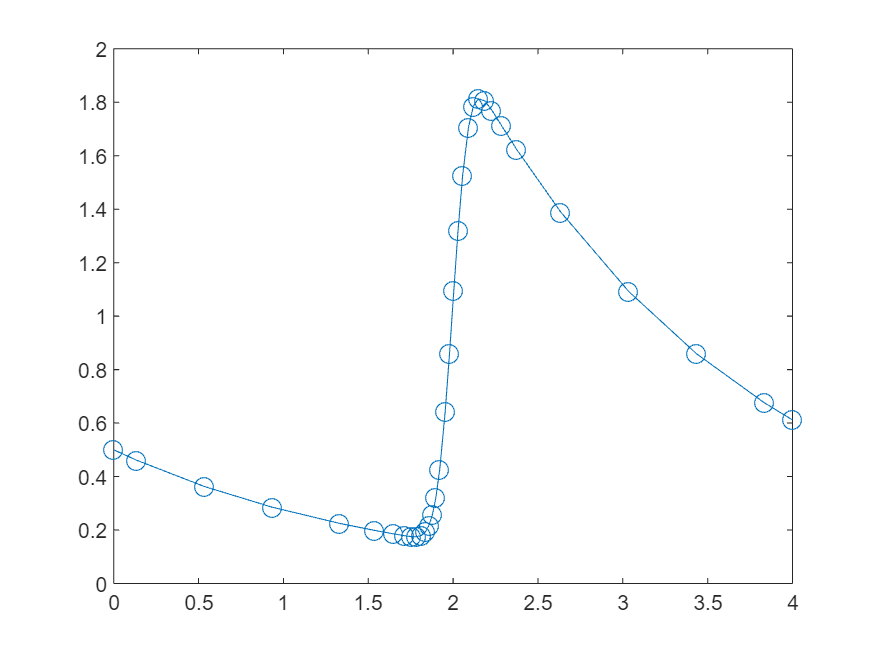


[t , y] = ode23(@dydt, [0, 4], 0.5);
plot(t,y,'-o','MarkerSize',9)

size(t)

ans =     33     1



options = odeset('RelTol', 1e-5);

options = struct with fields:
              AbsTol: []
                 BDF: []
              Events: []
         InitialStep: []
            Jacobian: []
           JConstant: []
            JPattern: []
                Mass: []
        MassSingular: []
            MaxOrder: []
             MaxStep: []
         NonNegative: []
         NormControl: []
           OutputFcn: []
           OutputSel: []
              Refine: []
              RelTol: 1.0000e-05
               Stats: []
          Vectorized: []
    MStateDependence: []
           MvPattern: []
        InitialSlope: []

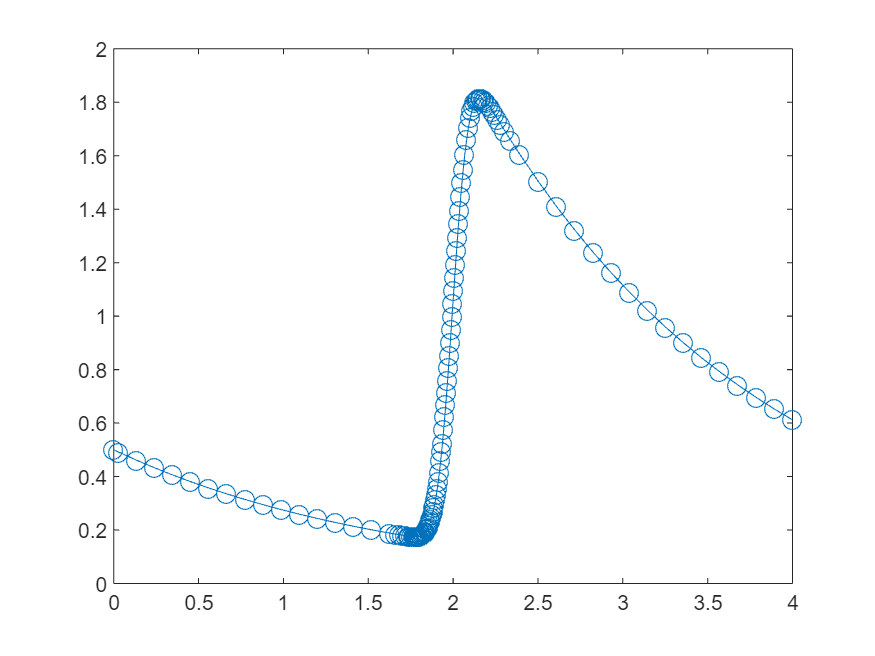

[t , y] = ode23(@dydt, [0, 4], 0.5,options);
plot(t,y,'-o','MarkerSize',9)

size(t)

ans =    119     1


Systems of ODEs

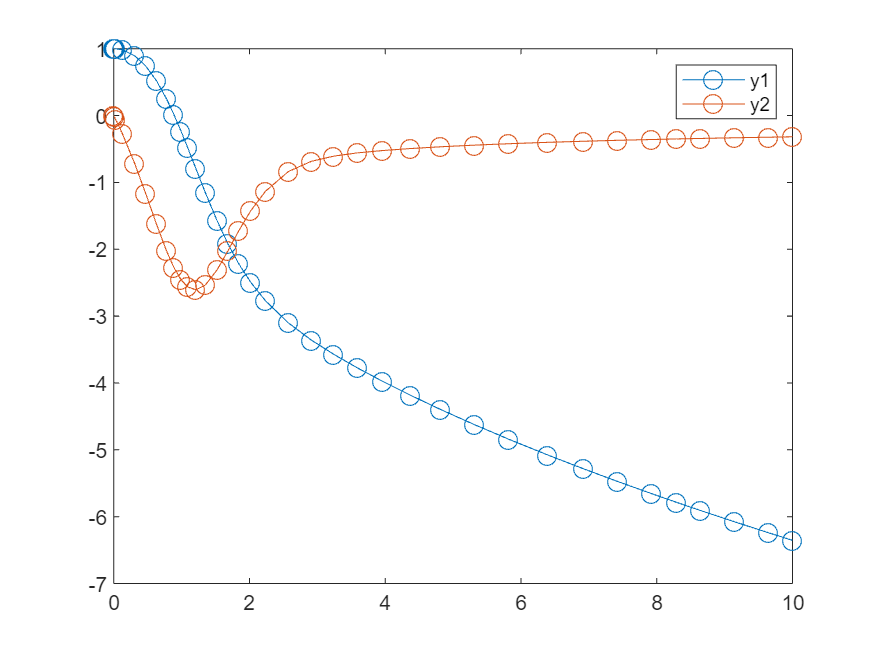

[t, y] = ode23(@myODE, [0,10], [1;0]);
plot(t,y,'-o','MarkerSize',9)
legend('y1','y2')

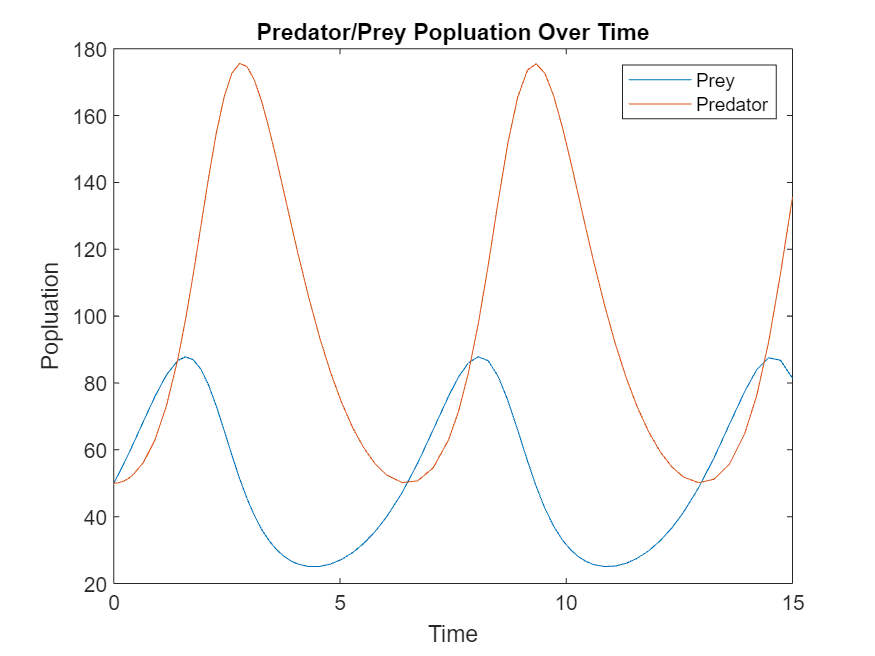

t0 = 0;
tfinal = 15;

p0 = [50, 50];

[t, p] = ode45(@lotkaODE, [t0, tfinal], p0);

plot(t,p)
title("Predator/Prey Popluation Over Time")
ylabel('Popluation')
xlabel("Time")
legend('Prey', 'Predator')

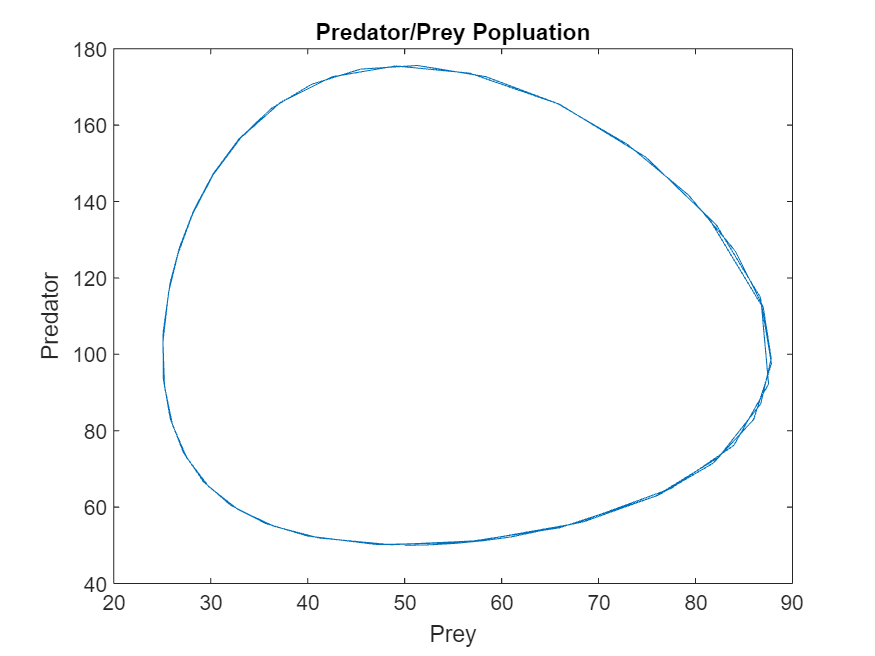


plot(p(:,1),p(:,2))
title("Predator/Prey Popluation")
xlabel("Prey")
ylabel('Predator')

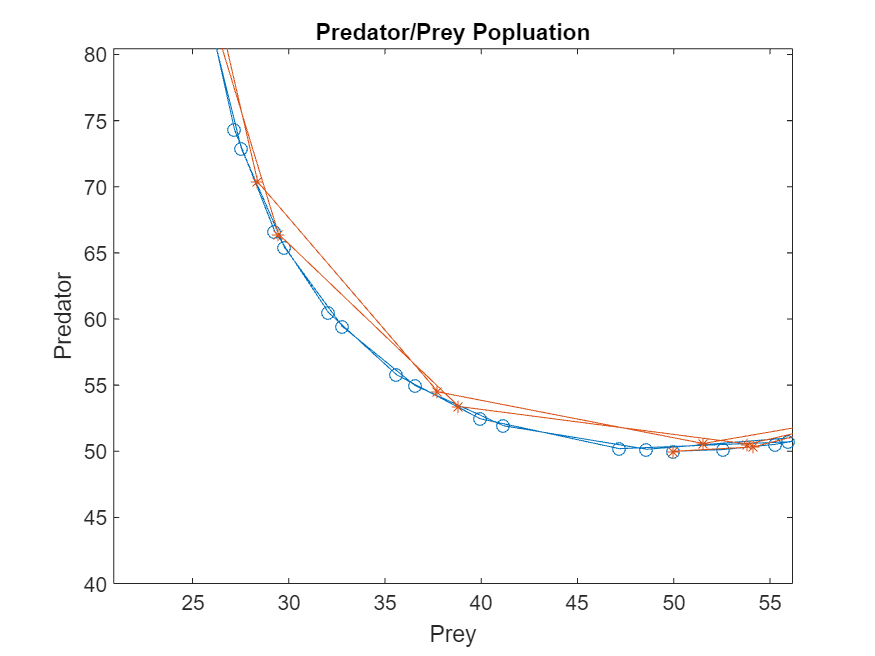


[t45, p45] = ode45(@lotkaODE, [t0, tfinal], p0);
[t23, p23] = ode23(@lotkaODE, [t0, tfinal], p0);

plot(p45(:,1),p45(:,2), '-o', p23(:,1),p23(:,2), '-*')
title("Predator/Prey Popluation")
xlabel("Prey")
ylabel('Predator')

Lorenz System - Chaos

close all
lorenz = @(t,f,sigma, rho, beta) [ sigma*(f(2)-f(1));
                                   f(1)*(rho - f(3)) - f(2);
                                   f(1)*f(2) - beta*f(3)]

lorenz = function_handle with value:
    @(t,f,sigma,rho,beta)[sigma*(f(2)-f(1));f(1)*(rho-f(3))-f(2);f(1)*f(2)-beta*f(3)]


s = 10;
b = 8/3;
r = 28;

mylorenz = @(t,f) lorenz(t, f ,s, r, b)

mylorenz = function_handle with value:
    @(t,f)lorenz(t,f,s,r,b)

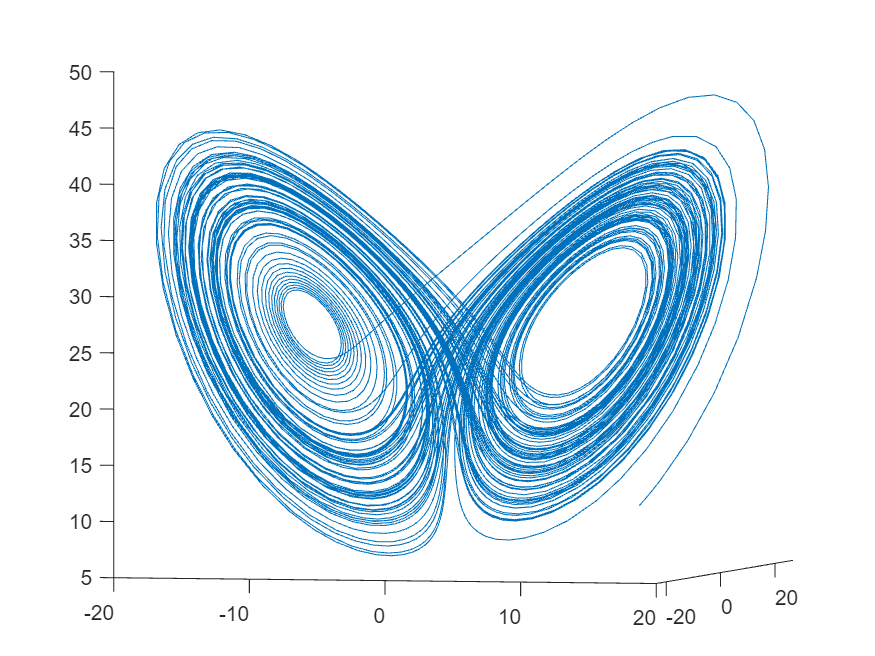


ft0 = [10, 20, 10];
[t, f] = ode45(mylorenz, [0,100], ft0);
plot3(f(:,1),f(:,2),f(:,3))
view([14.1 2.7])



ft0 = [5,5,5]

ft0 =      5     5     5


[t1, f1] = ode45(mylorenz, [0,100], ft0);
ft0 = [5.001,5,5]

ft0 =     5.0010    5.0000    5.0000


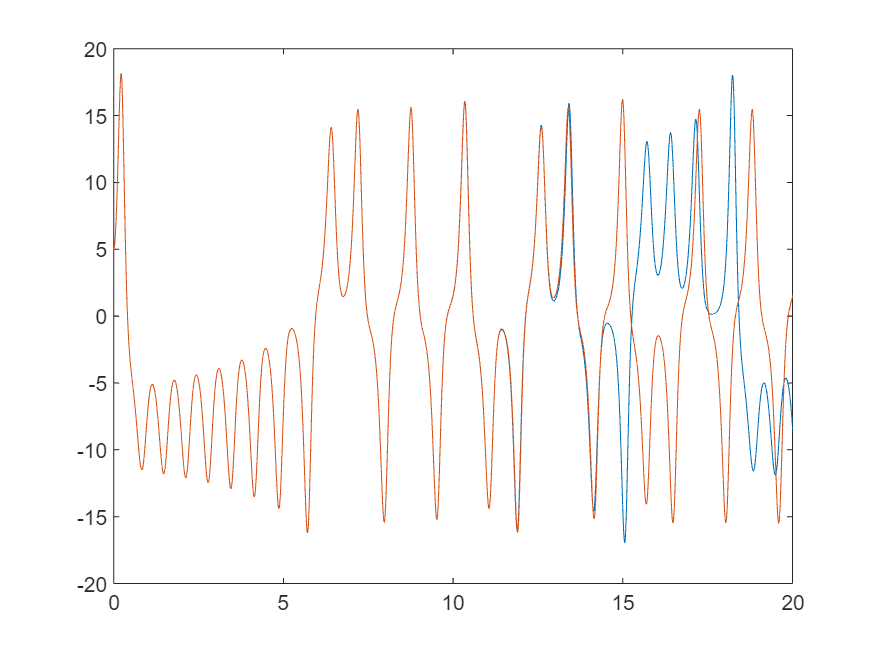

[t2, f2] = ode45(mylorenz, [0,100], ft0);

plot(t1,f1(:,1))
hold on
plot(t2,f2(:,1))
hold off
xlim([0,20])

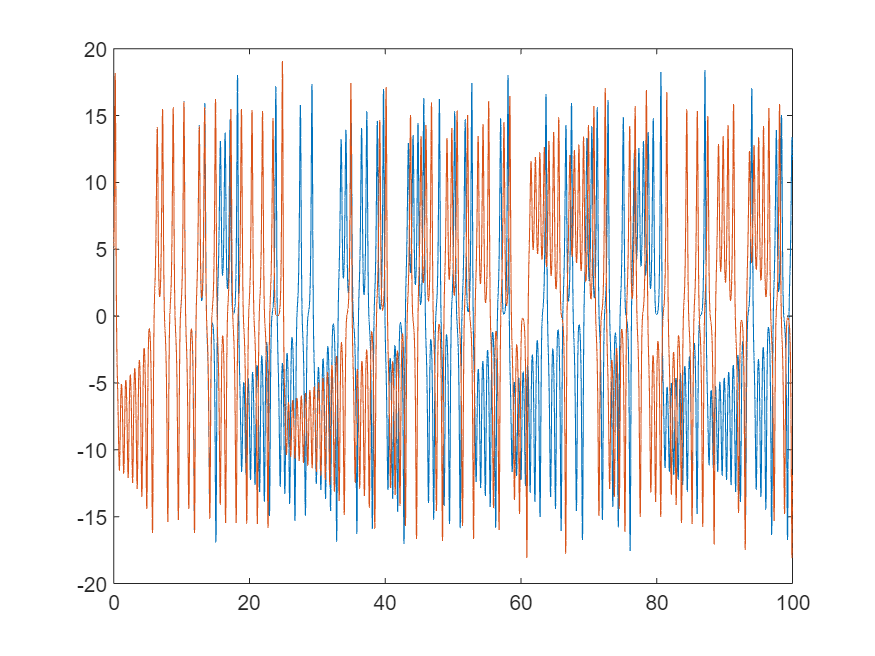



plot(t1,f1(:,1))
hold on
plot(t2,f2(:,1))
hold off

Higer Order ODE

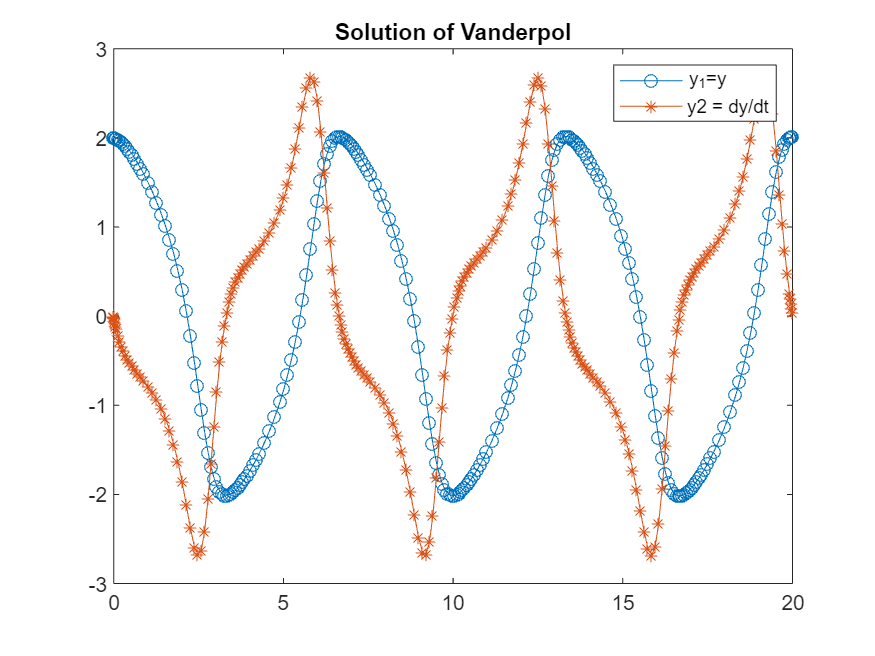

[t, y] = ode45(@vdp1, [0,20], [2;0]);

plot(t,y(:,1),'-o',t,y(:,2),'-*')
title("Solution of Vanderpol")
legend('y_1=y', 'y2 = dy/dt')

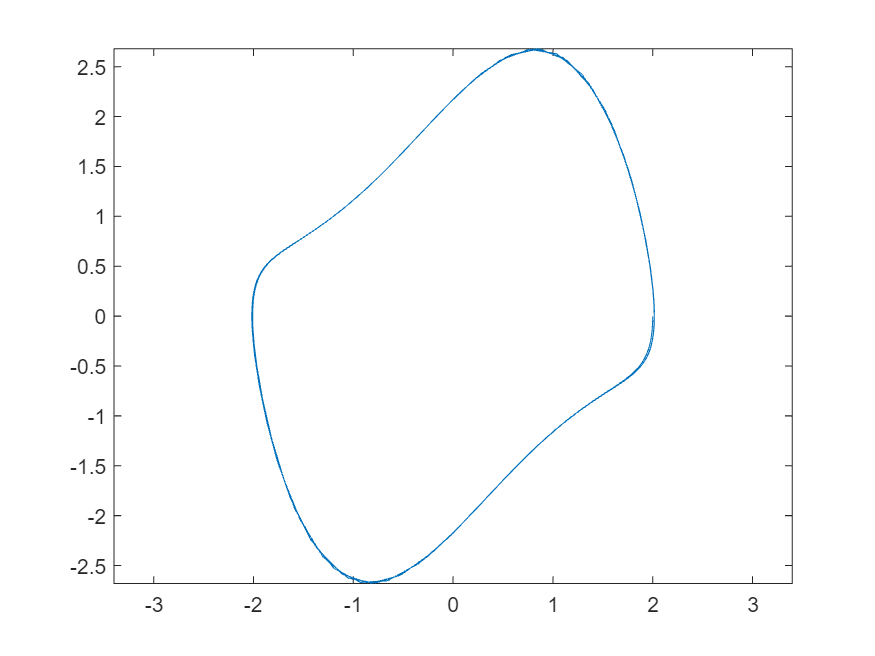

plot(y(:,1),y(:,2))
axis equal

mu = [0.01 0.11 0.5 1 1.5 2 2.5 3 3.5 4]

mu =     0.0100    0.1100    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


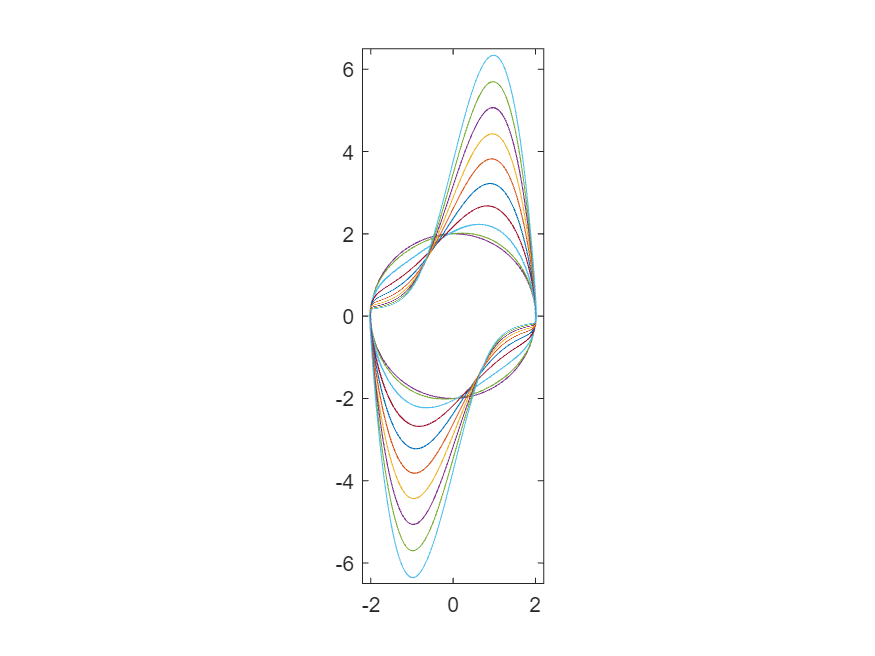


for i = 1:length(mu)
    
    myvdp = @(t,y) vdp2(t,y,mu(i));
    [t,y] = ode45(myvdp, [0:0.01:20], [2;0]);
    plot(y(:,1),y(:,2));
    hold on
end

axis equal
xlim([-2.2 2.2])
ylim([-6.5 6.5])

hold off

Stiff Problem

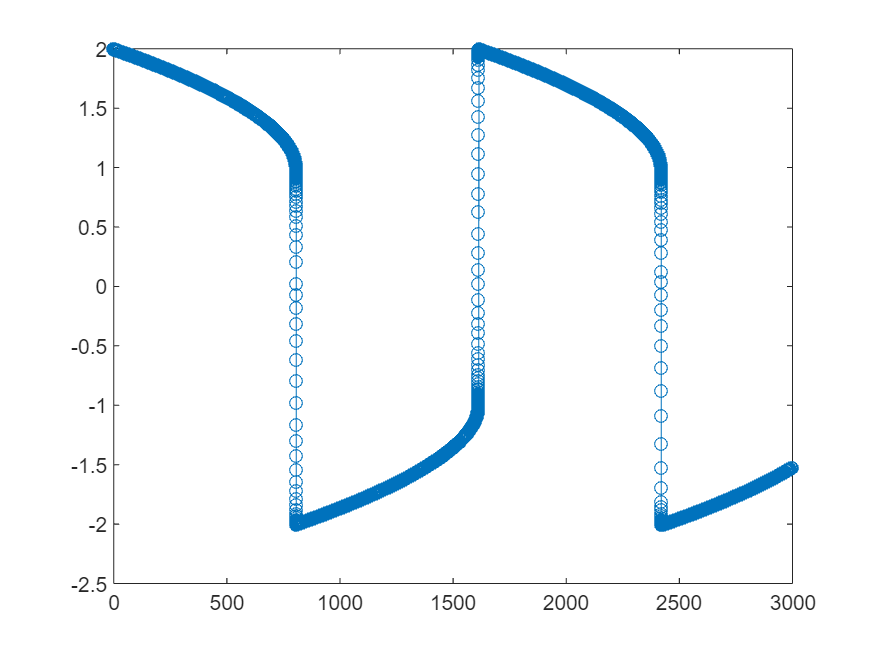

close all
mu = 1000;

myvdp = @(t,y) vdp2(t,y,mu);
tic;
[t,y] = ode45(myvdp, [0, 3000], [2;0]);
t1 = toc;
plot(t,y(:,1),'-o')

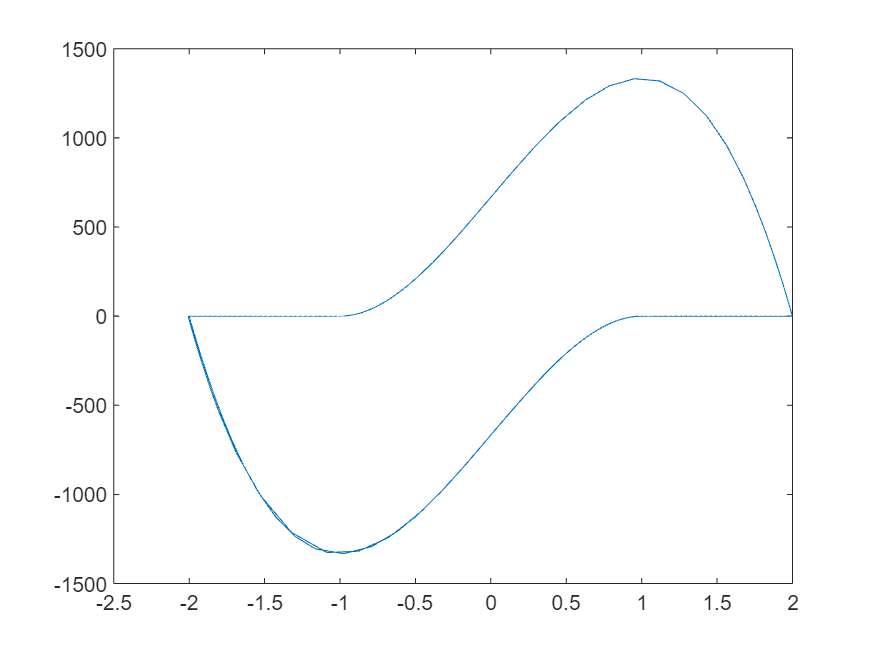

plot(y(:,1),y(:,2));

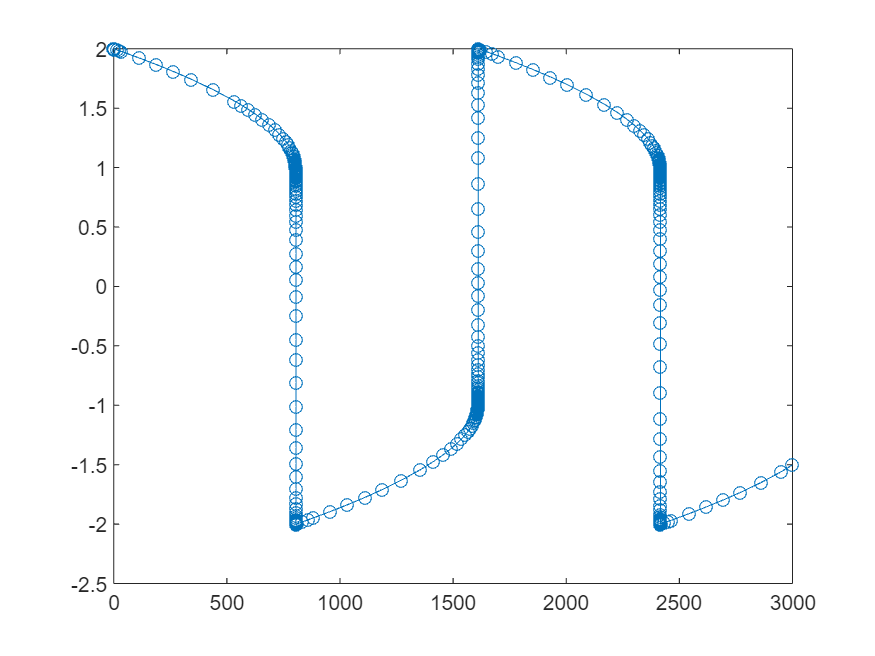



tic;
[t,y] = ode15s(myvdp, [0, 3000], [2;0]);
t2 = toc;
plot(t,y(:,1),'-o')

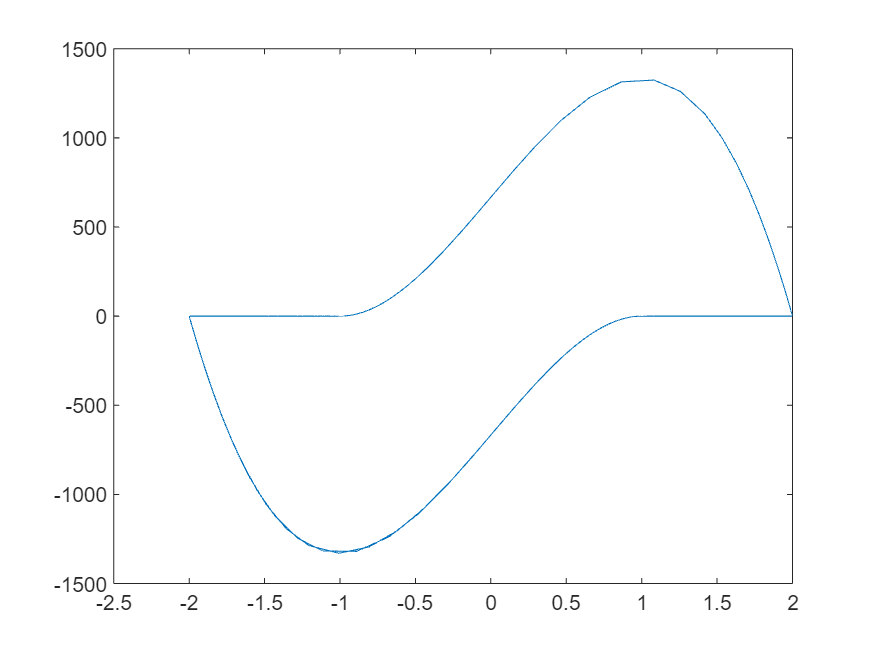

plot(y(:,1),y(:,2));


t1/t2

ans = 90.2122

Implicit ODE

%doc ode15i

y0 = sqrt(3/2);

roots([3/2 -3/2*sqrt(3/2), 2, -sqrt(3/2)])

ans =    0.2041 + 0.9789i
   0.2041 - 0.9789i
   0.8165 + 0.0000i


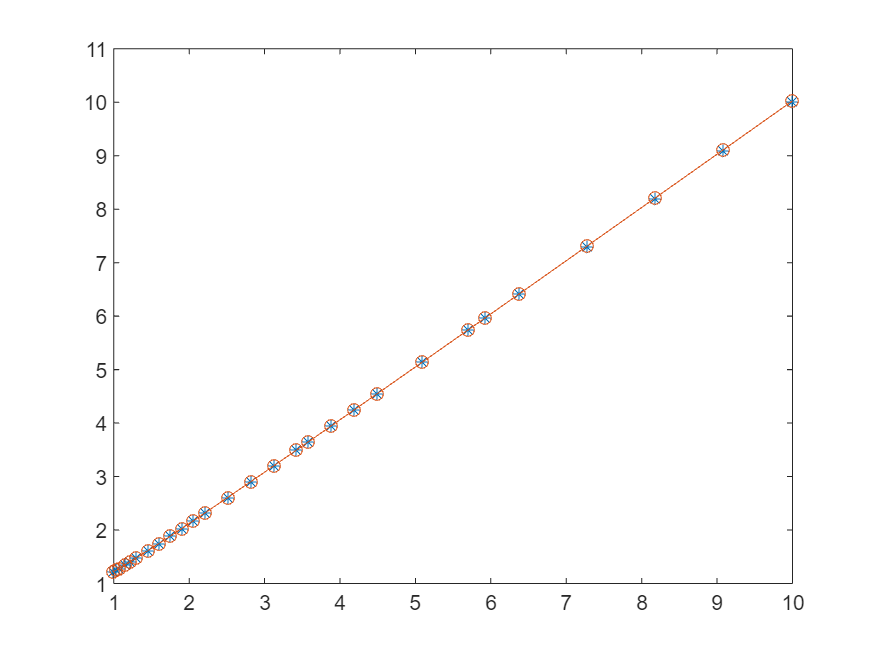


yp0 = 0.8165;

[t, y] = ode15i(@weissinger, [1 10], y0, yp0);

ytrue = sqrt(t.^2 + 0.5);
plot(t,y,'*', t, ytrue, '-o')

Boundary Value Problem

%doc bvp4c

x = linspace(0,10,10);

solinit = bvpinit(x, [0 1])

solinit = struct with fields:
    solver: 'bvpinit'
         x: [0 1.1111 2.2222 3.3333 4.4444 5.5556 6.6667 7.7778 8.8889 10]
         y: [2×10 double]
     yinit: [0 1]

solinit.y

ans =      0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1


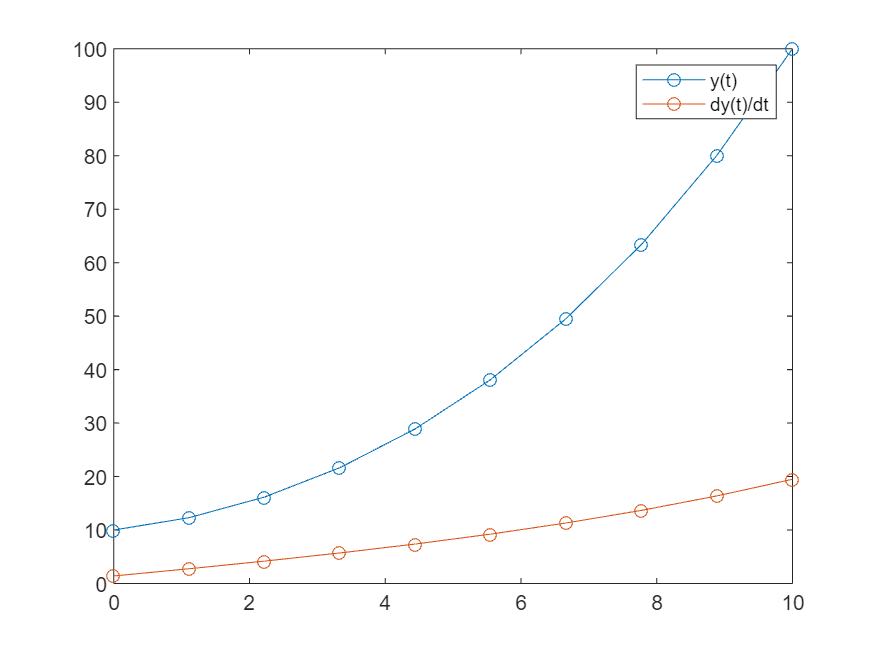


sol = bvp4c(@ODE_BVP, @bcfun1, solinit);

t = sol.x;
y = sol.y;

plot(t,y,'-o')
legend('y(t)', 'dy(t)/dt')